# Laboratory 3: Di Via, Graziani, Hiller-Szala

## Introduction 

**Swarm Intelligence (SI)** is a part of artificial intelligence that takes inspiration from biology and the collective behavior of natural systems like ant colonies, bee swarms, bird flocks, and fish schools. In these systems, each agent (like an ant or a bird) has limited abilities, but by following simple rules and working together, the group can solve complex problems. One of the most well-known algorithms in this area is **Ant Colony Optimization (ACO)**.

 ACO is inspired by the foraging behavior of real ants. In fact ants are capable of finding the shortest path from a food source to their nest just by **exploiting pheromone** information. While walking, ants deposit pheromone on the ground and follow, with some probability, pheromone previously deposited by other ants. This process can be visualized with the following figure:

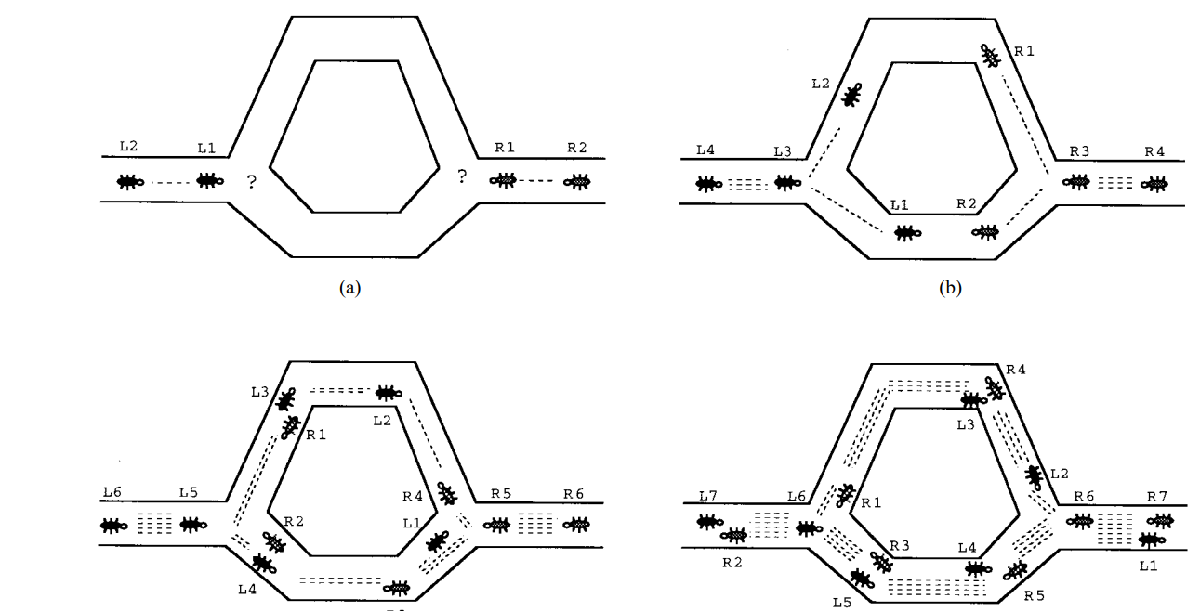

Imagine ants arriving at a decision point, where they must choose between turning left or right. At first, since they have no idea which way is better, they choose randomly: about half go left and half go right. Supposing that all ants walk at approximately the same speed but one path is shorter, the ants taking that shorter path will return sooner and go back more times. As a result, pheromone accumulates faster. Over time, this difference in pheromone levels starts to influence the decision of new ants coming into the system. They are more likely to follow the path with more pheromone, which is the shorter one. This creates a positive feedback loop: more ants choose the better path, which increases the pheromone even more, and soon almost all ants follow the shortest route. The above behavior of real ants has inspired ant system, an algorithm in which a set of artificial ants cooperate to the solution of a problem by exchanging information via pheromone deposited on graph edges. 

ACO is particularly effective for solving the **Traveling Salesman Problem (TSP)**, an NP-hard problem important in combinatorial optimization and operation research, that involves finding the shortest possible route visiting a set of cities exactly once and returning to the starting point.  By mimicking ant behavior, ACO explores different tour combinations and iteratively improves the solution based on pheromone updates.

## Mathematical Background 

 Utilizing a graph representation of the **travelling salesman problem** (**TSP**), the question we ask is the following: "Given a list of N cities $V = \{a_1, \ldots, a_N\} $, the set of arcs connecting the cities together$A = \{(r,s) | r,s \in V\}$ and the distances between each pair of cities $\delta(r,s)$, what is the shortest possible route that visits each city exactly once and returns to the origin city?"

The core idea behind ACO is to have a group of agents, called ants, that work in parallel to find good solutions to the TSP. These ants cooperate indirectly by using pheromones, which allow them to communicate globally without talking to each other directly. So in addition to the cost measure $\delta(r,s)$, each edge has also an attractivity measure, called pheromone $\tau(r,s)$, which is updated at run time by artificial ants. In this report ant system is applied to symmetric instances of the TSP with $\delta(r,s)=\delta(s,r)$ (therefore $\tau(r,s)=\tau(s,r)$), but it also works in asymmetric scenarios, known as the Asymmetric Traveling Salesman Problem (ATSP) with $\delta(r,s) \neq \delta(s,r)$ and $\tau(r,s) \neq \tau(s,r)$. 

## State Transition Rule

Each ant builds a solution **iteratively**: it starts with an empty route and adds one city at a time. When choosing the next city, the ant decision is based on:

- **Exploitation**: ants rely on **pheromone trails** on each edge $\tau(r,s)$, which represent the collective memory of previous ants;

- **Exploration**: ants use **heuristic information**, typically based on the **distance between cities**, to discover new or potentially better routes.

The next city is chosen according to a state transition rule, called** pseudo-random-proportional rule**. Given $J_k(r)$ the set of cities not visited yet by ant $k$ positioned on city $r$, the ant chooses to move to the city $s \neq r$ to by applying the rule given by: 

$s =
\begin{cases}
\arg\max\limits_{u \in J_k(r)} \left\{ [\tau(r,u)] \cdot [\eta(r,u)]^\beta \right\} & \text{if} \quad q \le q_0 \\
S & \text{otherwise} 
\end{cases}$,

where 

- $\eta(r,u)$ is the inverse of the distance $\delta(r,u)$; 

- $\beta >0$  is a parameter which determines the relative importance of pheromone versus distance;

- $q$ is a random number uniformly distributed in $[0, 1]$;

- $q_0$ is a parameter balancing exploitation ( if $q \leq q_0$) and exploration ( if $q<q_0$);

- $S$ and is a random variable selected according to the probability distribution, given by: 

$P(S = s) = p_k(r,s) =
\begin{cases}
\frac{[\tau(r,s)] \cdot [\eta(r,s)]^\beta}{\sum\limits_{u \in J_k(r)} [\tau(r,u)] \cdot [\eta(r,u)]^\beta} & \text{if} \quad s \in J_k(r) \\
0 & \text{otherwise}
\end{cases}$.

This rule encourages transitions towards cities which are connected by short edges with a high amount of pheromone without completely eliminating the possibility of following less favorable paths.

## Local Updating Rule

While building a solution (a tour) of the TSP, ants visit edges and change their pheromone level by applying the local updating rule. Given $\rho \in (0,1)$ a parameter, set a priori, that regulates the step of the updates, the rule is the following:

$\tau(r,s) \leftarrow (1 - \rho) \tau(r,s) + \rho \Delta \tau(r,s)$.

Four different strategies about local updating rule, depending on the term $\Delta \tau(r,s)$, have been experimented in the original paper *Ant Colony System: A Cooperative Learning Approach to the Traveling Salesman Problem *by the authors Marco Dorigo and Luca Maria Gambardella:

- **Ant-Q**: first strategy inspired by Q-learning, a reinforcement learning algorithm where an agent learns the best action to take in each state based on feedback from the environment. In this context, ants must decide which city to visit next based on their current location. Therefore, the pheromone update term was set to $\Delta \tau(r,s)=\gamma \cdot \max_{z \in J_k(s)} \tau(s,z)$ with $\gamma \in (0,1)$, mirroring the Q-learning approach;

- **Ant Colony System (ACS):** the second strategy consists in setting $\Delta \tau(r,s)=\tau_0$ as the initial pheromone level;

- **Ant Colony (AC):** the third strategy consists in setting $\Delta \tau(r,s)=0$, meaning no additional pheromone is added;

- **None: t**he fourth strategy consists in not applying local pheromone updates at all, similar to the original Ant System algorithm.

In the paper scenarios (set of five randomly generated 50-city TSP’s,  the Oliver30 symmetric TSP and the ry48p asymmetric TSP)  the approaches *AC* and *None* performed the worst. The two best approaches were *Ant-Q* and *ACS* in terms of performance but *ACS  *resulted to be preferable because it's computationally simpler. 

The purpose of the local update rule is to dynamically reduce the desirability of recently used edges, encouraging diversity in the tours constructed by ants. This helps avoid premature convergence by spreading exploration across different parts of the search space. Without local updates, ants would tend to exploit the same limited set of high-pheromone edges.

## Global Updating Rule

Once all ants have completed their tours, only the globally best ant is allowed to deposit pheromone. To update the pheromone level, the algorithm applies the **global updating rule**:


$$\tau(r,s) \leftarrow (1 - \alpha) \tau(r,s) + \alpha \Delta \tau(r,s)$$


where $\alpha \in (0,1)$  is the pheromone decay parameter, and $\Delta \tau(r,s) =
\begin{cases}
(L_{gb})^{-1} & \text{ if }(r,s) \in \text{ global-best-tour} \\
0 & \text{otherwise}
\end{cases}$ with $L_{gb}$ is the length of the **globally best tour from the beginning of the trial**.

Global updating rule is performed after all ants have completed their tours and it is intended to provide a greater amount of pheromone to shorter tours. Only these edges receive additional pheromone, while pheromone on all other edges gradually evaporates. The original authors also tested a different global update method called **iteration-best**, which reinforces edges from the **best tour found in the current iteration** rather than the best tour ever found (called **global-best**). In the original scenario, experiments showed little difference between these two approaches, with a slight advantage for the global-best method, which is the one used in their work. For sake of curiosity, we still implemented both global-best (looking at the best path ever since the beginning of the loop) and iteration-best (looking only at the best path of the single iteration considered).

## Stop criterion

After the global updating rule is applied, the algorithm keeps track of the best tour found so far throughout the entire run. The process of ants constructing solutions and updating pheromones (both locally during solution construction and globally after all ants have completed their tours) is repeated iteratively.

The algorithm stops when a predefined stopping criterion is satisfied. Common stopping criteria include reaching a **maximum number of iterations or observing no improvement** in the best solution for a specified **number of consecutive iterations.** Once the stopping condition is satisfied, the algorithm terminates, returning the best tour found as the approximate solution to the TSP.

## Laboratory Introduction 

The purpose of this lab is to implement a Swarm Intelligence algorithm, the ACO algorithm, to determine the shortest path, Lbest, for the TSP visiting 27 European capitals, ensuring that each city is visited only once and the tour ends by returning to the starting city.

## Step 0: Importing Data 

As first step the data, presenting the geographical coordinates identifying the cities, are imported. Data must be organised into 7 columns as follows: 

**Columns 1 to 3:** latitude degrees, minutes and direction (North, South, West, East);

 **Columns 4 to 6**: longitude degrees, minutes and direction (North, South, West, East); 

**Column 7:** name of the city

In this case the data is provided in the file "capitali EU.txt". Each imported data is then converted into cartesian plane coordinates through a **Pseudo-Mercatore Projection.** It is a cylindrical map projection, which represents lines of latitude and longitude as straight lines to facilitate navigation. The conversion follows this formula:

**Decimal degrees = Degrees + (Minutes / 60)**,

with the sign determined by the hemisphere:

-  **positive** for north latitudes N and east longitudes E;

- **negative** for south latitudes S and west longitudes W.

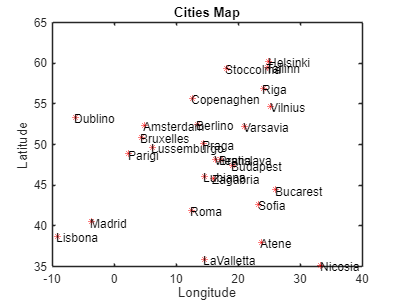

clear; clc; close all;

%------------------------------------------------------------------------------------
%--------------------------------READING COORDINATES---------------------------------
%------------------------------------------------------------------------------------
%Generalizing for each input data, as long as its structured as described in the previous caption
data_filename=input('Insert the data filename.txt presenting the cities coordinates for TSP: \n','s');
%Example:
%data_filename='capoluoghi_italia.txt';
%data_filename='capitali_EU.txt';
%data_filename='brightest_stars.txt'; 
%The coordinates are based on standard astronomical data (Hipparcos catalog or Gaia data releases).
%Right Ascension (RA) is converted from hours to degrees by multiplying by 15. Declination (Dec) is already in degrees.
%'N' or 'S' indicating the hemisphere while 'E' indicating the celestial coordinate system's eastward measurement.

[city_names,cities,n]=read_cities_coordinates(data_filename);

%------------------PLOT--------------------------
%Plot
figure();
plot(cities(:,1),cities(:,2), 'r*'); %Plotting cities as longitude-latitude coordinates
title('Cities Map');
text(cities(:,1)-0.2,cities(:,2)-0.2,city_names); %Adding city names to the plot
xlabel('Longitude'); ylabel('Latitude');

## Step I: ACO Algorithm

Different strategies have been used to solve the problem, which make the initialization of ants vary:

- There are $m$ ants. Each of them start in a different city (randomly assigned) and, after each tour, start again from the **same** city. 

- There are $m$ ants. Each of them start in a different city (randomly assigned) and, after each tour, start again from a **different** city.

- There are $m$ ants and they all start from the same city (at each iteration).

- The number of ants corresponds to the number of cities $m = n$. Each starts from a random city. 

In every approach used, tours start and end in the same city.

The parameters used are mostly the same as the one used in the original paper, obtained by a preliminary optimization phase, in which the authors found that the experimental optimal values of the parameters were largely independent of the problem. The parameters are:

- $\beta=2$ Parameter that regulates the relative importance of pheromone vs distance;

- $q_0=0.9$ Parameter that regulates the exploration vs exploitation balance;

- $\alpha=0.1$ Parameter that regulates the decay of the pheromone in the global updates;

- $\rho=0.1$Parameter that regulates the pace of local updates;

- $\tau_0=(n \cdot L_{nn})^ {-1}= 2.2  \times 10^{-4}$ Initial pheromone level of all possible traits (inferred using the Nearest Neighbor algorithm, where $L_{nn}$ is the tour length produced by the nearest neighbor heuristic and $n$ is the number of cities;

- $m=10$ for the first three strategies, and $m=n=27$ for the last one; It represents the number of artificial ants; 

- $\gamma=0.8$ is the discount factor in Q-learning (used in Q-Ant local updating rule). Specifically, **γ** determines how much the future expected pheromone (or future reward) influences the local pheromone update on an edge;

- *max_iter=*2500 is the maximum number of iterations for the method;

- *stop=*10 is a parameter counting for how many iterations the minimum path doesn't improve.

%------------------------------------------------------------------------------------
%----------------------ACO PARAMETERS INITIALIZATION---------------------------------
%------------------------------------------------------------------------------------

%rng(42); %Fixing a seed

%Parameters
beta=2;
q0=0.9;
alpha=0.1;
rho=alpha;
tau0=2.2e-4;
m=10;
max_iter=2500;
stop=10;

%------------------------------------------------------------------------------------
%----------------------ACO STRATEGIES INITIALIZATION---------------------------------
%------------------------------------------------------------------------------------

%Strategy Selection
strategy_list={'1: m ants start from fixed random cities', ...
    '2: m ants start from new random cities each iteration', ...
    '3: All m ants start from the same city', ...
    '4: Each m=n ant start from a unique different city'};

[strategy, ~]=listdlg('PromptString', {'Select the ACO strategy to use:'}, ...
    'SelectionMode', 'single', 'ListString', strategy_list);

if isempty(strategy) %Checking strategy selection not cancelled
    error('Strategy not selected!');
else
    fprintf('Strategy %d selected!', strategy);
end

Strategy 4 selected!


%If strategy 3 is choosen, all the ants start from the same city.
%User can choose the starting city (for example Rome)
if strategy==3
    city_list=cellstr(city_names);

    [city, ~]=listdlg('PromptString', {'Select the starting city:'}, ...
        'SelectionMode', 'single', 'ListString', city_list);

    if isempty(city) %Checking city selection not cancelled
        error('City not selected!');
    else
        fprintf('All the ants starting from "%s"!', city_list{city});
    end

elseif strategy==4 %If strategy 4 is chosen
    m=n; %The number of ants must be the same number as the cities
end


%Local updating rule selection
local_update_options={'Q-Ant', 'ACS', 'AC', 'None'};

[local_update_rule, ~]=listdlg('PromptString', {'Select the local updating rule:'}, ...
    'SelectionMode', 'single', 'ListString', local_update_options);

if isempty(local_update_rule) %Checking local updating rule selection not cancelled
    error('Local Updating Rule not selected!');
else
    selected_rule=local_update_options{local_update_rule};
    fprintf('Local Updating Rule "%s" selected!\n', selected_rule);
end

Local Updating Rule "ACS" selected!



%Global updating rule selection
global_update_options={'Global Best', 'Iterative Best'};

[global_update_rule, ~]=listdlg('PromptString', {'Select the local updating rule:'}, ...
    'SelectionMode', 'single', 'ListString', global_update_options);

if isempty(global_update_rule) %Checking global updating rule selection not cancelled
    error('Global Updating Rule not selected!');
else
    selected_rule=global_update_options{global_update_rule};
    fprintf('Global Updating Rule "%s" selected!\n', selected_rule);
end

Global Updating Rule "Global Best" selected!



%Clearing unused variables
clear local_update_options; clear global_update_options; clear selected_rule;
clear strategy_list; clear city_list;


The following cell contains the core of the algorithm, referring to the pseudocode of the original paper reported below. First, the distance matrix between all cities and the corresponding matrix of inverse distances $\eta$ are computed. Next, the variables for storing the best tour, the stopping criterion counter, and the best path length (initialized to infinity) are initialized. The algorithm then proceeds to execute as described in the Mathematical Background section.

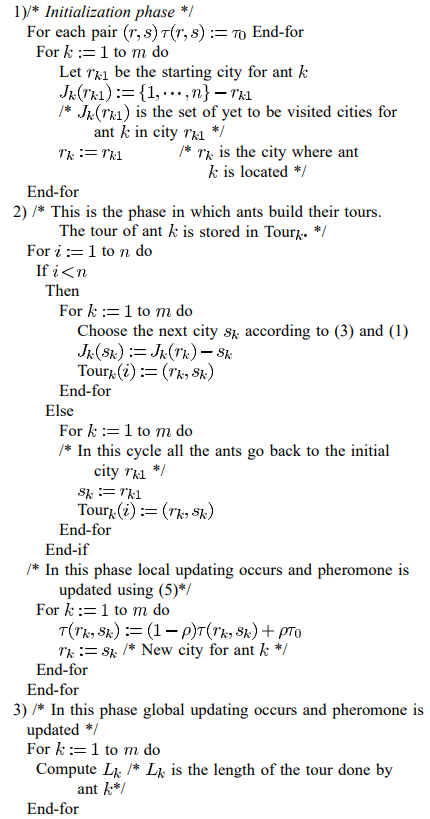

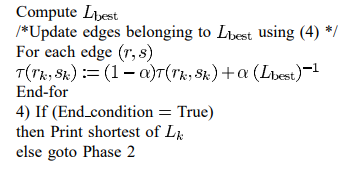

%------------------------------------------------------------------------------------
%--------------------------------ACO ALGORITHM---------------------------------------
%------------------------------------------------------------------------------------
%The designed ACO function requires in input city value and gamma value
%Defining city as a parameter that will be ignored if strategy is not the third
if strategy~=3
    city = NaN; %Ignored
end

%Defining gamma as a parameter that will be ignored if local updating rule is not Q-Ant
if local_update_rule==1
    gamma=0.2; %Defining the discount factor parameter
else
    gamma=NaN; %Ignored
end

%Calling ACO function, city and gamma are optional parameters pre-defined
%and ignored in case the situation doesn't involve them
[bestTour, best_distance, total_Lbest, min_distance, total_Lmin, iter]=ACO(cities, m, alpha, rho, beta, q0, tau0, stop, max_iter, strategy, city, local_update_rule, gamma, global_update_rule);


## Step II: Results Analysis

Our experiments aimed to evaluate the performance of different ACO configurations by combining four main strategies S1,S2,S3,S4 with the four local updating rules L1, L2, L3, L4 and the two global updating rules G1, G2. The evaluation was based on metrics such as convergence speed (number of iterations) and best tour (length and starting-ending cities), matched with a qualitative behaviour plot. 

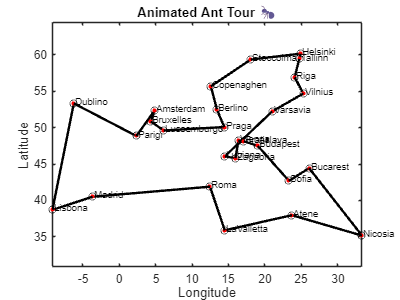

%---------------------------------------------------------------------
%---------------------------RESULTS: VIDEO----------------------------
%---------------------------------------------------------------------
figure;
plot(cities(:,1),cities(:,2),'ko');  %Plotting all cities in the map
hold on;
text(cities(:,1)+0.2,cities(:,2)+0.2,city_names,'FontSize',8); %Plotting city names
title('Animated Ant Tour 🐜');
xlabel('Longitude'); ylabel('Latitude');
axis equal;
%Animating the tour step-by-step
for i = 1:n
    c1 = bestTour(i);
    c2 = bestTour(i+1);
    plot([cities(c1,1),cities(c2,1)], [cities(c1,2),cities(c2,2)],'k-','LineWidth',2); %Drawing edges between the nodes
    plot(cities(c2,1),cities(c2,2),'r.','MarkerSize',10); %Drawing nodes reached
    pause(0.5);  %Animation speed parameter
end


%Printing the best tour in terms of cities
disp('Best tour:');

Best tour:


disp(city_names(bestTour(1:end-1))); %Last entrance is the starting city

    {'Amsterdam'  }
    {'Bruxelles'  }
    {'Lussemburgo'}
    {'Praga'      }
    {'Berlino'    }
    {'Copenaghen' }
    {'Stoccolma'  }
    {'Helsinki'   }
    {'Tallinn'    }
    {'Riga'       }
    {'Vilnius'    }
    {'Varsavia'   }
    {'Lubiana'    }
    {'Zagabria'   }
    {'Vienna'     }
    {'Bratislava' }
    {'Budapest'   }
    {'Sofia'      }
    {'Bucarest'   }
    {'Nicosia'    }
    {'Atene'      }
    {'LaValletta' }
    {'Roma'       }
    {'Madrid'     }
    {'Lisbona'    }
    {'Dublino'    }
    {'Parigi'     }



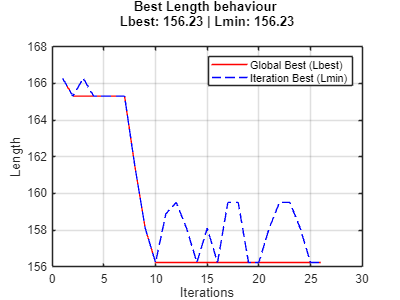


%------------------------------------------------------------------------------------
%--------------------------------LENGTH PLOT-----------------------------------------
%------------------------------------------------------------------------------------

%Plotting best length behaviour along the iterations
figure();
plot(1:iter,best_distance(1:iter),'r-','DisplayName','Global Best (Lbest)');
hold on;
plot(1:iter,min_distance(1:iter),'b--','DisplayName','Iteration Best (Lmin)');
title(sprintf('Best Length behaviour \n Lbest: %.2f | Lmin: %.2f \n',total_Lbest,total_Lmin));
xlabel('Iterations'); ylabel('Length');
legend('show');
grid on;


%Clearing unused variables;
clear c1; clear c2; clear i; clear iter; 

The plot shows the evolution of the tour length along the algorithm's iterations. Specifically, we compare:

- **Lbest (Global Best)**: the shortest tour length found across all iterations up to the current iteration;

- **Lmin (Iteration Best)**: the shortest tour length found within the current iteration.

%Plots obtained for every combination of strategy, local update rule and global update rule
%Strategy 3 is starting from Rome
%Parameters are the same fixed as before
f1=openfig('Lplot_local1-2.fig', 'new', 'visible');
fig2=openfig('Lplot_local3-4.fig', 'new', 'visible');

In most configurations, the two plots  of Lbest and Lmin overlap early and remain **nearly identical** throughout the iterations (such as S2 L1 G2 or S4 L1 G1). This suggests that the ants consistently rediscover the global best solution, leading to rapid convergence and a** strong emphasis on exploitation**. In fact this behavior is typically associated with the use of the **global-best pheromone updating rule (G1) or the Q-Ant local updating rule (L1)**, which are known to emphasize exploitation, rather than iteration-best global updating rule (G2) or other local updating rules (especially L3 and L4). 

**Strategy 4**, in particular, shows this overlapping behavior in most of its configurations ( except of S4 L2 G2 and S4 L4 G2), hinting it may be the **most effective** strategy overall.

On the contrary**, occasional spikes** in the Lmin curve mean the ants fail to rediscover the global best solution. This is likely due to low pheromone reinforcement, **weak exploitation**, or **elevated stochasticity** during the tour construction phase. Such behavior is highlighted in configurations using the **iteration-best global update rule (G2)** and local update rules that do not enhance pheromone trails effectively **(like the AC updating rule L3 and None updating rule L4)**. 

While the **global-best rule** ensures fast convergence and stability, it may reduce the algorithm's exploratory capabilities, increasing the risk of **premature convergence** and potentially overlooking better solutions. 

These observations can be summarized by the concept of trade-off between exploration and exploitation in ACO algorithms described in Mathematical Background Section. The commented code below has been used to generate all the plots for the different strategies and updating rules combinations.

% %Defining parameters
% strategies=1:4;
% local_update_rules=1:4;
% global_update_rules=1:2;
% gamma=0.20;
% m=10;
% city = 13; %Rome
% rng(42);
% 
% %Setting subplot parameters
% %Counting total number of combinations
% num_configs=length(strategies)*length(local_update_rules)*length(global_update_rules);
% %Computing subplot grid size
% rows=ceil(sqrt(num_configs));
% cols=ceil(num_configs / rows);
% %Creating single figure
% figure('Name', 'ACO Configurations: Lbest and Lmin Behaviour', 'NumberTitle', 'off');
% config_idx=0;
% 
% %Looping over all strategy/local/global combinations
% for strategy=strategies
%     for local_rule=local_update_rules
%         for global_rule=global_update_rules
%             config_idx=config_idx + 1;
%             if strategy==4
%                 m=n;
%             end
%             [bestTour, best_distance, total_Lbest, min_distance, total_Lmin, iter]=ACO(cities, m, alpha, rho, beta, q0, tau0, stop, max_iter, strategy, city, local_rule, gamma, global_rule);
%             %Plotting
%             subplot(rows, cols, config_idx);
%             plot(1:iter, best_distance(1:iter), 'r-', 'LineWidth', 1);
%             hold on;
%             plot(1:iter, min_distance(1:iter), 'b--', 'LineWidth', 1);
%             title(sprintf('S%d L%d G%d\nLb: %.1f | Lm: %.1f', strategy, local_rule, global_rule, total_Lbest, total_Lmin));
%             xlabel('Iter'); ylabel('Len');
%             grid on;
%             if config_idx==1
%                 legend('Lbest','Lmin');
%             end
%         end
%     end
% end


The following analysis is based on three independent runs on the c**apitali_EU.txt** dataset. Results were saved in the file `aco_results_comparison_run....txt`. The corresponding code used to generate and filter these results is commented and presented below.

In particular the following analysis are made taking in consideration the subset of data corresponding to the **best-performing configurations, **those achieving or closely approaching the optimal tour with a **length of around 153** (the minimum value registered during the three independent runs). Data can be found in the file `best_results.txt`, but it's also reported down below the code cell.

## Initialization Strategies Comparison

The four initialization strategies showed distinct performances:

- **Strategy 4** proved to be the **most effective** overall, appearing in 9 out of the 22 best-performing configurations. This superior performance is likely due to its use of the largest ant population, equal to the number of cities, combined with initialization from every city. This setting enhanced the exploration of the solution space and enabled the strategy to consistently discover high-quality solutions, including multiple instances of the optimal tour length (**Lbest = 153.3879**). While it generally showed strong performance, it occasionally exhibited larger **discrepancies** between **Lbest** and **Lmin** when paired with the **iteration-best** global update rule (G2);

- **Strategy 2** also demonstrated **strong performance**, appearing in 9 out of the 22 best-performing configurations. By using 10 ants with random starting cities at each tour, it achieved an effective balance between **computational efficiency** and exploratory diversity, requiring fewer iterations to converge compared to the other strategies and still consistently producing both optimal (**153.3879**) and near-optimal (**153.7302**) tour lengths;

- **Strategy 1** showed more **limited effectiveness**, appearing in only 4 out of 22 best results. While it achieved optimal solutions when successful **(Lbest: 153.3879)**, the fixed starting city approach appears to constrain exploration compared to the more flexible initialization strategies;

- **Strategy 3** was completely **absent** from the best results, despite experiments were done considering strategy 3 twice: first with Roma as starting city and later with Helsinki as starting city. This confirms its theoretical weakness: all ants starting from the same city severely limits exploration diversity and leads to suboptimal performance.

## Local Updating Rules Comparison

The **local pheromone updating rules** exhibited clear differences in terms of performance:

- **Ant-Q (Local Rule 1)** emerged as the **dominant local updating rule**, appearing in 14 out of 22 best results across all experimental runs. It achieved the best tour length (**153.3879**) when combined with **Strategies 1, 2, **and** 4**, demonstrating robustness across different initialization strategies. The Q-learning-inspired updates appear to provide effective reinforcement guiding ants toward high-quality solutions;

- **ACS (Local Rule 2)** showed **moderate performance** being able to achieve the optimal tour length in some configurations, but less consistently than Ant-Q.  It also exhibited high variability in convergence speed, suggesting less robustness than Ant-Q, but better overall performance than L3 or L4;

- **AC (Local Rule 3)** performed **better than expected**. While it was not the most frequently selected rule in optimal configurations, it **achieved the optimal tour length (153.3879)** in **Strategy 4, Run 1**, and a **near-optimal tour (153.7302)** in **Strategy 2, Run 1**. This shows that despite lacking additional pheromone reinforcement, it can still be effective when paired with favorable strategy and update rule settings;

- **None (Local Rule 4)**, surprisingly was **not entirely ineffective**. While it lacked the reinforcement benefits of the other rules, it still **produced near-optimal results (153.7302)** in **multiple configurations** (like Strategy 2, Run 2 & Run 3 and Strategy 4, Run 2). However, its **inability to reinforce good decisions locally** can still be considered as a weakness.

## Global Updating Rules Comparison

Both global updating strategies (Global-Best and Iteration-Best) appeared in the optimal solutions:

- **Global-Best (Global Rule 1)** appeared in some optimal configurations, particularly **effective** when **combined with Ant-Q **local updates (L1); 

- **Iteration-Best (Global Rule 2)**, however, appeared more frequently among the best configurations in our experiments, especially when **paired with Strategies 2 and 4**. By reinforcing the best solution of each iteration, this rule enables faster adaptation and better balance between exploration and exploitation, leading to more consistent convergence.

While the authors of the original paper observed a slight advantage for global-best under certain conditions, our results suggest that **iteration-best performs more robustly** across diverse settings in this problem instance.

## Other General Observations

The optimal tour length of **153.3879** was consistently achieved across multiple strategy and parameter combinations, indicating the presence of a **global optimum**. A secondary close solution with a tour length of **153.7302** also appeared frequently, suggesting the existence of a nearby local optimum. Among the European capitals **Helsinki–Stoccolma,** **Nicosia–Bucarest **and** Lubiana-Lussemburgo **repeatedly appeared as starting city and ending city in best tour solutions, highlighting their geographic efficiency. 

**Convergence speeds** varied widely, with the number of iterations to reach optimality ranging from **12 to 52**. In general **Strategy 2** tended to reach optimal solutions more quickly while **Strategy 1 and 4** achieved consistent high-quality results with moderate convergence times.

The combination that most reliably achieved the optimal tour length is given by **Strategy 4/1 + Ant-Q (Local Rule 1) + Iteration-Best (Global Rule 2)**

%Computing data with different combinations of strategy, starting city, local rules, gamma values, global rules
% %Defining parameters
% gammas=[0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9];
% 
% strategies= 1:4;
% local_update_rules=1:4;
% global_update_rules=1:2;
% m=10;
% city_list=[13,8]; %Rome, Helsinki
% num_runs=3;
% seeds=[42, 100, 150];
% 
% for run=1:num_runs
%     %Setting a seed for reproducibility
%     rng(seeds(run));
%     %Creating the file in which collect the results
%     filename=sprintf('aco_results_comparison_run%d_%s', run, data_filename);
%     fileID=fopen(filename, 'w'); % Open file for writing
%     text=sprintf('\n Run %d | Seed: %d | Comparing ACO strategies for different local/global update rules \n', run, seeds(run));
%     fprintf(fileID, text);
% 
%     for strategy=strategies
%         for local_update_rule=local_update_rules
%             if local_update_rule==1
%                 for gamma=gammas
%                     for global_update_rule=global_update_rules
%                         if strategy==3
%                             for city=city_list
%                                 %Printing the strategy and rules used
%                                 text = sprintf('\nStrategy %d | Local Rule %d | Gamma %.2f | Global Rule %d\n', strategy, local_update_rule, gamma, global_update_rule);
%                                 fprintf(fileID, text);
%                                 %Calling ACO function
%                                 [bestTour, best_distance, total_Lbest, min_distance, total_Lmin, iter]=ACO(cities, m, alpha, rho, beta, q0, tau0, stop, max_iter, strategy, city, local_update_rule, gamma, global_update_rule);
%                                 %Printing the length results and iteration
%                                 text = sprintf('Lbest: %.4f | Lmin: %.4f | Iter: %d\n', total_Lbest, total_Lmin, iter);
%                                 fprintf(fileID, text);
%                                 %Printing the starting city and ending city of the best tour
%                                 text = sprintf('Start city: %s | End city: %s\n', city_names{bestTour(1)}, city_names{bestTour(end-1)});
%                                 fprintf(fileID, text);
%                                 %Printing the Lmin and Lbest per iteration
%                                 %fprintf(fileID, 'Lmin per iter: %s\n', num2str(min_distance(1:iter), '%.2f, '));
%                                 %fprintf(fileID, 'Lbest per iter: %s\n', num2str(best_distance(1:iter), '%.2f, '));
%                             end
% 
%                         elseif strategy==4
%                             m=n;
%                         end
% 
%                         text = sprintf('\nStrategy %d | Local Rule %d | Gamma %.2f | Global Rule %d\n', strategy, local_update_rule, gamma, global_update_rule);
%                         fprintf(fileID, text);
%                         [bestTour, best_distance, total_Lbest, min_distance, total_Lmin, iter]=ACO(cities, m, alpha, rho, beta, q0, tau0, stop, max_iter, strategy, city, local_update_rule, gamma, global_update_rule);
%                         text = sprintf('Lbest: %.4f | Lmin: %.4f | Iter: %d\n', total_Lbest, total_Lmin, iter);
%                         fprintf(fileID, text);
%                         text = sprintf('Start city: %s | End city: %s\n', city_names{bestTour(1)}, city_names{bestTour(end-1)});
%                         fprintf(fileID, text);
%                     end
%                 end
%             else    
%                 gamma=0.2;
%                 for global_update_rule=global_update_rules
%                     if strategy==3
%                         for city=city_list
%                             %Printing the strategy and rules used
%                             text = sprintf('\nStrategy %d | Local Rule %d | Gamma %.2f | Global Rule %d\n', strategy, local_update_rule, gamma, global_update_rule);
%                             fprintf(fileID, text);
%                             %Calling ACO function
%                             [bestTour, best_distance, total_Lbest, min_distance, total_Lmin, iter]=ACO(cities, m, alpha, rho, beta, q0, tau0, stop, max_iter, strategy, city, local_update_rule, gamma, global_update_rule);
%                             %Printing the length results and iteration
%                             text = sprintf('Lbest: %.4f | Lmin: %.4f | Iter: %d\n', total_Lbest, total_Lmin, iter);
%                             fprintf(fileID, text);
%                             %Printing the starting city and ending city of the best tour
%                             text = sprintf('Start city: %s | End city: %s\n', city_names{bestTour(1)}, city_names{bestTour(end-1)});
%                             fprintf(fileID, text);
%                             %Printing the Lmin and Lbest per iteration
%                             %fprintf(fileID, 'Lmin per iter: %s\n', num2str(min_distance(1:iter), '%.2f, '));
%                             %fprintf(fileID, 'Lbest per iter: %s\n', num2str(best_distance(1:iter), '%.2f, '));
%                         end
% 
%                     elseif strategy==4
%                         m=n;
%                     end
% 
%                     text = sprintf('\nStrategy %d | Local Rule %d | Gamma %.2f | Global Rule %d\n', strategy, local_update_rule, gamma, global_update_rule);
%                     fprintf(fileID, text);
%                     [bestTour, best_distance, total_Lbest, min_distance, total_Lmin, iter]=ACO(cities, m, alpha, rho, beta, q0, tau0, stop, max_iter, strategy, city, local_update_rule, gamma, global_update_rule);
%                     text = sprintf('Lbest: %.4f | Lmin: %.4f | Iter: %d\n', total_Lbest, total_Lmin, iter);
%                     fprintf(fileID, text);
%                     text = sprintf('Start city: %s | End city: %s\n', city_names{bestTour(1)}, city_names{bestTour(end-1)});
%                     fprintf(fileID, text);
%                 end
%             end
%         end
%     end
%     fclose(fileID);
%     pause(1);
% 
% end

Here, we report the subset of data corresponding to the **best-performing configurations, **those achieving or closely approaching the optimal tour with a length of around 153. We recall that only local rule 1 (Ant-Q) is taking in account the gamma value.

`Run 1`

`Strategy 1 | Local Rule 1 | Gamma 0.20 | Global Rule 2`

`Lbest: 153.3879 | Lmin: 153.3879 | Iter: 36`

`Start city: LaValletta | End city: Atene`

`Strategy 2 | Local Rule 3 | Gamma 0.20 | Global Rule 2`

`Lbest: 153.7302 | Lmin: 153.7302 | Iter: 40`

`Start city: Helsinki | End city: Stoccolma`

`Strategy 4 | Local Rule 1 | Gamma 0.50 | Global Rule 2`

`Lbest: 153.8331 | Lmin: 160.7760 | Iter: 23`

`Start city: Lubiana | End city: Lussemburgo`

`Strategy 4 | Local Rule 2 | Gamma 0.20 | Global Rule 2`

`Lbest: 153.7302 | Lmin: 153.7302 | Iter: 40`

`Start city: Helsinki | End city: Stoccolma`

`Strategy 4 | Local Rule 3 | Gamma 0.20 | Global Rule 2`

`Lbest: 153.3879 | Lmin: 153.3879 | Iter: 27`

`Start city: Nicosia | End city: Bucarest`

`Run 2`

`Strategy 1 | Local Rule 1 | Gamma 0.10 | Global Rule 1`

`Lbest: 153.3879 | Lmin: 153.3879 | Iter: 18`

`Start city: Atene | End city: Nicosia`

`Strategy 1 | Local Rule 1 | Gamma 0.30 | Global Rule 2`

`Lbest: 153.3879 | Lmin: 153.3879 | Iter: 29`

`Start city: Nicosia | End city: Bucarest`

`Strategy 1 | Local Rule 1 | Gamma 0.50 | Global Rule 2`

`Lbest: 153.7302 | Lmin: 158.7448 | Iter: 44`

`Start city: Helsinki | End city: Stoccolma`

`Strategy 2 | Local Rule 1 | Gamma 0.40 | Global Rule 2`

`Lbest: 153.3879 | Lmin: 153.3879 | Iter: 32`

`Start city: Lubiana | End city: Lussemburgo`

`Strategy 2 | Local Rule 1 | Gamma 0.70 | Global Rule 1`

`Lbest: 153.3879 | Lmin: 165.8021 | Iter: 41`

`Start city: Madrid | End city: Roma`

`Strategy 2 | Local Rule 1 | Gamma 0.80 | Global Rule 2`

`Lbest: 153.3879 | Lmin: 161.3270 | Iter: 12`

`Start city: Lubiana | End city: Lussemburgo`

`Strategy 2 | Local Rule 4 | Gamma 0.20 | Global Rule 2`

`Lbest: 153.7302 | Lmin: 153.7302 | Iter: 39`

`Start city: Helsinki | End city: Stoccolma`

`Strategy 4 | Local Rule 1 | Gamma 0.10 | Global Rule 1`

`Lbest: 153.3879 | Lmin: 153.3879 | Iter: 22`

`Start city: Nicosia | End city: Bucarest`

`Strategy 4 | Local Rule 1 | Gamma 0.60 | Global Rule 2`

`Lbest: 153.9001 | Lmin: 159.7993 | Iter: 41`

`Start city: Lubiana | End city: Lussemburgo`

`Strategy 4 | Local Rule 2 | Gamma 0.20 | Global Rule 1`

`Lbest: 153.3879 | Lmin: 157.7068 | Iter: 27`

`Start city: Lubiana | End city: Lussemburgo`

`Strategy 4 | Local Rule 4 | Gamma 0.20 | Global Rule 2`

`Lbest: 153.7302 | Lmin: 153.7302 | Iter: 52`

`Start city: Nicosia | End city: Bucarest`

`Run 3`

`Strategy 2 | Local Rule 1 | Gamma 0.20 | Global Rule 1`

`Lbest: 153.7302 | Lmin: 153.7302 | Iter: 37`

`Start city: Helsinki | End city: Stoccolm`

`Strategy 2 | Local Rule 1 | Gamma 0.60 | Global Rule 2`

`Lbest: 153.3879 | Lmin: 165.9987 | Iter: 26`

`Start city: Lubiana | End city: Lussemburgo`

`Strategy 2 | Local Rule 2 | Gamma 0.20 | Global Rule 2`

`Lbest: 153.7302 | Lmin: 160.8259 | Iter: 17`

`Start city: Helsinki | End city: Stoccolma`

`Strategy 2 | Local Rule 4 | Gamma 0.20 | Global Rule 1`

`Lbest: 153.7302 | Lmin: 153.7302 | Iter: 30`

`Start city: Helsinki | End city: Stoccolma`

`Strategy 4 | Local Rule 1 | Gamma 0.40 | Global Rule 2`

`Lbest: 153.3879 | Lmin: 153.3879 | Iter: 32`

`Start city: Lubiana | End city: Lussemburgo`

`Strategy 4 | Local Rule 1 | Gamma 0.60 | Global Rule 2`

`Lbest: 153.3879 | Lmin: 162.3567 | Iter: 16`

`Start city: Lubiana | End city: Lussemburgo`

## Functions

#### `Read_cities_coordinates` 

Function, able to read coordinates in .txt files (structured as described in Step 0 section) and to convert them into decimal degrees coordinates.

function [city_names,cities,n]=read_cities_coordinates(filename)

%INPUTS:
%filename: name of the .txt file containing city coordinates (string or char)
%
%OUTPUTS:
%city_names: cell array of city names
%cities: array n X 2 of [longitude, latitude] coordinates in decimal degrees
%n: number of cities (scalar)
%
%------------------------------------------------------------------------------------------------------------
%---------------------------------------------------INPUT CHECKS---------------------------------------------
%------------------------------------------------------------------------------------------------------------

%Checking the number of inputs
if nargin~=1
    error('The number of inputs must be 1');
end

%Checking is filename is char or string and .txt file
if ~(ischar(filename) || isstring(filename) || endsWith(filename,'.txt', 'IgnoreCase',true))
    error('Input filename must be a character array or string, ending with .txt extension!');
end

%Checking if file exists in the current directory
if ~isfile(filename)
    error('File "%s" does not exist!',filename);
end

%------------------------------------------------------------------------------------------------------------
%---------------------------------------------------MAIN-----------------------------------------------------
%------------------------------------------------------------------------------------------------------------

%Opening file and reading the data
fid=fopen(filename);
C=textscan(fid,'%f %f %c %f %f %c %s');
fclose(fid);

%----------------------------------------------------------------------
%-----------------------FILE STRUCTURE CHECK---------------------------
%----------------------------------------------------------------------

%Checking that the file is structured with 7 columns
if length(C)~=7
    error('File structure should made up of 7 columns!');
end

% Check that all columns have the same size (no missing values)
size=length(C{1});

if size<2
    error('File must contain at least two pair of cities coordinates.');
end

for i=2:length(C)
    if length(C{i})~=size
        error('All columns must have the same number of rows — possible missing values.');
    end
end


%Checking latitude columns are numeric vectors
if ~isnumeric(C{1}) || ~isnumeric(C{2}) || ~isvector(C{1}) || ~isvector(C{2})
    error('Latitude degrees and minutes (respectively in first and second column) must be numeric vectors.');
end
%Checking longitude columns are numeric vectors
if ~isnumeric(C{4}) || ~isnumeric(C{5}) || ~isvector(C{4}) || ~isvector(C{5})
    error('Longitude degrees and minutes (respectively in fourth and fifth column) must be numeric vectors.');
end
%Checking degrees are positive integers
if any(C{1}<0 | floor(C{1})~=C{1}) || any(C{4}<0 | floor(C{4})~=C{4})
    error('Latitude and longitude degrees (respectively in first and fourth column) must be positive integers.');
end
%Checking minutes are integers between 0 and 59
if any(C{2}<0 | C{2}>=60 | floor(C{2})~=C{2}) || any(C{5}<0 | C{5}>=60 | floor(C{5})~=C{5})
    error('Latitude and longitude minutes (respectively in second and fifth column) must be integers in the range 0 to 59.');
end
%Checking that direction columns are char arrays
if ~ischar(C{3}) || ~ischar(C{6})
    error('Latitude and longitude directions (respectively in third and sixth column) must be character arrays.');
end
%Checking that direction columns present only N,S,W,E symbols
if any(~ismember(C{3}, ['N', 'S'])) || any(~ismember(C{6}, ['E', 'W']))
    error('Latitude and longitude directions (respectively in third and sixth column) must be respectively only N/S and E/W.');
end
%Checking that city names are a cell array of strings or chars
if ~iscell(C{7})
    error('City names must be a cell array of strings or characters.');
end


%----------------------------------------------------------------------
%----------------------------------MAIN--------------------------------
%----------------------------------------------------------------------
%Converting the coordinates through Mercatore Projection to plot them in Cartesian plane

%Latitude (y)
column1=C{1}; %Importing latitude degrees
column2=C{2}; %Importing latitude minutes
latitude=column1 + column2 / 60; %Converting latitude into decimal degrees
sign_lat=find(C{3}=='S'); %Finding indices for south latitudes
latitude(sign_lat)=-latitude(sign_lat); %Assigning negative value to south latitudes

%Longitude (x)
longitude=C{4} + C{5} / 60; %Converting longitude into decimal degrees
sign_long=find(C{6}=='W'); %Finding indices for west longitudes
longitude(sign_long)=-longitude(sign_long);  %Assigning negative value to west longitudes

%Defining cities names and number of cities
city_names=C{7}; %Importing cities names
cities=[longitude, latitude]; %Defining the cities as pair of longitude and latitude
n=length(cities); %Defining total number of cities

end


#### `ACO function`

Function able to solve the Traveling Salesman Problem using different starting city-strategies, local/global pheromone update rules, and parameters.

function [bestTour, best_distance, total_Lbest, min_distance, total_Lmin, iter] = ACO(cities, m, alpha, rho, beta, q0, tau0, stop, max_iter, strategy, city, local_update_rule, gamma, global_update_rule)
%
%INPUTS:
%cities: matrix of city coordinates (n x 2)
%m: number of artificial ants (positive integer scalar)
%alpha: pheromone decay parameter in global update (scalar in (0,1))
%rho: pheromone decay parameter in local update (scalar in (0,1))
%beta: heuristic importance parameter (positive scalar)
%q0: exploitation-exploration balancing parameter (scalar in [0,1])
%tau0: initial pheromone value on each edge (positive scalar)
%stop: maximum number of iterations without best tour length improvement (positive integer scalar)
%max_iter: maximum number of iterations
%strategy: ant starting strategy (integer scalar in {1,2,3,4})
%1: each ant starts from a random city (fixed per ant)
%2: each ant starts from a different random city at each iteration
%3: all ants start from the same pre-defined city
%4: each ant starts from a unique city (m=n)
%city: starting city index in strategy 3 (optional, integer scalar in {1,...,n})
%local_update_rule: index of local updating rule selected (scalar in {1,2,3,4})
% 1: Q-Ant
% 2: ACS
% 3: Ant Colony (AC)
% 4: none
%gamma: discount factor in Q-Ant updating rule (optional, scalar in (0,1))
%global_update_rule: index of global updating rule selected (scalar in {1,2})
% 1: global-best
% 2: iteration-best
%
%OUTPUTS:
%bestTour: best tour found overall (1 x n+1)
%best_distance: best tour length (overall) at each iteration (1 x iter)
%total_Lbest: total length of bestTour
%min_distance: best tour length at each individual iteration (1 x iter)
%total_Lmin: total length of shortest tour in last iteration
%iter: number of iterations before convergence of the algorithm

%------------------------------------------------------------------------------------
%--------------------------------------INPUT CHECKS----------------------------------
%------------------------------------------------------------------------------------

%Defining the number of cities for TSP
n=length(cities);

%Check on number of inputs
if nargin~=14
    error("The number of inputs in the function must be 14.");
end
%Check on cities matrix
if ~ismatrix(cities) || size(cities,2)~=2
    error('The cities matrix (first input) must be a n x 2 matrix of coordinates.');
end

%Check on the number of ants
if ~isscalar(m) || m<=0 || floor(m)~=m
    error('The number of ants (second input) must be a positive scalar integer.');
end

%Check on alpha
if ~isscalar(alpha) || alpha<=0 || alpha>=1
    error('Alpha, the pheromone decay parameter in global update (third input), must be a scalar in (0,1).');
end

%Check on rho
if ~isscalar(rho) || rho<=0 || rho>=1
    error('Rho, the pheromone decay parameter in local update (fourth input),must be a scalar in (0,1).');
end

%Check on beta
if ~isscalar(beta) || beta<=0
    error('Beta, the heuristic importance parameter (fifth input), must be a positive scalar.');
end

%Check on q0
if ~isscalar(q0) || q0<0 || q0>1
    error('Q0, the exploitation-exploration balancing parameter (sixth input),must be a scalar in [0,1].');
end

%Check on tau0
if ~isscalar(tau0) || tau0<=0
    error('Tau0, the initial pheromone value (seventh input), must be a positive scalar.');
end

%Check on stop
if ~isscalar(stop) || stop<=0 || floor(stop)~=stop
    error('The maximum number of iterations without best tour length improvement (eighth input) must be a positive scalar integer.');
end

%Check on max_iter
if ~isscalar(max_iter) || max_iter<=0 || floor(max_iter)~=max_iter
    error('The maximum number of iterations (nineth input) must be a positive scalar integer.');
end

%Check on strategy and city
if ~ismember(strategy, 1:4)
    error('strategy (tenth input) must be one of: 1, 2, 3, 4.');
end

if strategy==4 && m~=n
    error('Strategy 4 requires number of ants (second input) to be equal to number of cities (number of rows of the first input).');
end

if strategy==3 && (isempty(city) || ~ismember(city, 1:n))
    error('Strategy 3 requires a valid "city" (eleventh input) as scalar integer between 1 and number of cities (number of rows of the first input).');
end

%Check on local update rule and gamma
if ~ismember(local_update_rule, 1:4)
    error('local_update_rule (twelfth input) must be one of: 1 (Q-Ant), 2 (ACS), 3 (AC), 4 (None).');
end

if local_update_rule==1 && (~exist('gamma', 'var') || gamma<=0 || gamma>=1)
    error('Local update rule 1 (Q-Ant) requires gamma (thirteenth input) to be defined as a scalar in (0,1).');
end

%Check on global update
if ~ismember(global_update_rule, 1:2)
    error('global_update_rule (fourteenth input) must be 1 (global-best) or 2 (iteration-best).');
end

%------------------------------------------------------------------------------------
%--------------------------------ACO INITIALIZATION----------------------------------
%------------------------------------------------------------------------------------

%Computing distance matrix n x n and matrix of inverse distances n x n
%Output of squareform is a symmetric matrix, the entrances of the matrix
%corresponds to the pairwise distance (pdist) between elements in "cities"
distance_matrix=squareform(pdist(cities));
eta=1./distance_matrix;
%Since the diagonal of the distance matrix is filled by zeros and the
%inverse is not defined, we remove the assigned inf values by assigning
%again zero value
eta(isinf(eta))=0;

%Initializing pheromone matrix n x n
%Ants are not releasing pheromone when not moving to another city
tau=tau0.*(1-eye(n)); %Pheromon value must be zero in the diagonal

%Initializing the best length as Inf
Lbest=Inf;

%Initializing the best tour vector (globally best path) of size 1 x (n+1)
%containing all the cities visited once, coming back to the starting city
bestTour=[];

%Initializing the min_distance and best_distance vectors 1 x max_iter
%containing the minimum tour length performed by the ants
min_distance=zeros(1,max_iter); %at each iteration
best_distance=zeros(1,max_iter); %overall

%Initializing a counter for the stopping criterion
%It will be updated whenever the best length doesn't improve
counter=0;

%Defining the starting city for each strategy used
if strategy==1
    %All ants starting from fixed random cities
    start_city=randperm(n,m);
elseif strategy==3
    %All ants starting from the same fixed city, chosen by the user
    start_city=city*ones(m,1);
elseif strategy==4
    %Each ant starts from a different city, with the number of ants
    %equal to the number of cities
    start_city=1:m;
end


%------------------------------------------------------------------------------------
%--------------------------------ACO ALGORITHM---------------------------------------
%------------------------------------------------------------------------------------

for iter=1:max_iter
    %Initializing the city tour of each ant m x (n+1)
    tour=zeros(m,n+1);
    %Initializing the tour length of each ant m x 1
    L=zeros(m,1);
    %Initializing the matrix of cities not visited yet by each ant m x n
    J=ones(m,n);

    %If strategy 2 is used, all ants start again from a different city after each tour
    if strategy==2
        start_city=randperm(n,m);
    end

    %Filling the first entrnace of the tour vector with the starting city
    %Assigning 0 value in the matrix of cities not visited yet in
    %correspondance of the starting city
    for k=1:m
        tour(k,1)=start_city(k);
        J(k,start_city(k))=0;
    end

    %Iteratively building the tour for each ant simultaneously
    for i=2:n+1
        for k=1:m
            r=tour(k,i-1); %Actual city of each ant

            %Applying the state transition rule to choose the next city
            if i<n+1
                %----------------------------------------------------------------------
                %------------------------STATE TRANSITION RULE-------------------------
                %----------------------------------------------------------------------
                %Implementing the pseudo-random proportional rule described in theoretical section.

                city_to_go = find(J(k,:)); % cities not visited yet
                tau_eta = tau(r, city_to_go) .* eta(r, city_to_go).^beta;

                %EXPLOITATION
                %the ants choose the next city with highest product of
                %pheromone intensity and heuristic desiderability (greedy choice)
                if rand <= q0
                    [~, index] = max(tau_eta);
                    %EXPLORATION
                    %the ants choose the next city based on a proportional selection (roulette wheel method)
                else
                    prob_city = tau_eta / sum(tau_eta); %Normalizing probabilities
                    cumulative = cumsum(prob_city);  %Computing cumulative distribution
                    index = find(cumulative >= rand, 1); %Finding the first city index exceeding a random number threshold
                end
                s = city_to_go(index);

            else %As final iteration occurs i==n+1, returning to the starting city
                s=tour(k,1);
            end

            %Assigning 0 value in the matrix of cities not visited yet in
            %correspondance of the new city chosen s
            J(k,s)=0;

            %Adding to the tour of each ant the new city chosen s
            tour(k,i)=s;

            %Computing the total distance of the tour for each ant adding
            %the length of each path from actual city r to the new city s
            L(k)=L(k)+distance_matrix(r,s);

            %----------------------------------------------------------------------
            %------------------------LOCAL UPDATING RULE---------------------------
            %----------------------------------------------------------------------
            %Local updating of pheromone on the edge just used
            if local_update_rule==1  %Q-Ant rule
                tau_max=max([tau(s, J(k,:) == 1), 0]);
                tau(r,s)=(1-rho)*tau(r,s)+rho*gamma*tau_max;

            elseif local_update_rule==2 %ACS rule
                tau(r,s)=(1-rho)*tau(r,s)+rho*tau0;

            elseif local_update_rule==3 %AC rule
                tau(r,s)=(1-rho)*tau(r,s);

            elseif local_update_rule==4 %None rule
                %No update
            end

            tau(s,r)=tau(r,s); %Pheromone matrix is symmetric in TSP
        end
    end
    %Saving the best solution of this iteration
    [Lmin,index] = min(L); %Selecting the shortest tour performed by the ants in this iteration
    if Lmin<Lbest
        Lbest=Lmin; %Saving the shortest tour as the best one ever
        bestTour=tour(index,:); %Saving the actual city tour corresponding to the shortest length
        counter=0; %Resetting counter for stop criterion
    else
        counter=counter+1; %Updating counter for stop criterion, meaning there's no improvement in terms of best length of the tour
    end

    %Saving the best length for each iteration and overall, in order to plot the length behaviour
    min_distance(iter)=Lmin;
    best_distance(iter)=Lbest;

    %----------------------------------------------------------------------
    %-----------------------GLOBAL UPDATING RULE---------------------------
    %----------------------------------------------------------------------
    %Applying global pheromone update based on selected rule
    if global_update_rule==1
        Tour=bestTour;  %Using global-best tour
        Delta_tau=alpha/Lbest;
    elseif global_update_rule==2
        Tour=tour(index,:); %Using iteration-best tour
        Delta_tau=alpha/Lmin;
    end

    tau=(1-rho)*tau; %Pheromon evaporates on all edges
    for i=1:n
        r=Tour(i);
        s=Tour(i+1);
        tau(r,s)=tau(r,s)+Delta_tau; %Reinforcing pheromon on the best edges
    end
    tau(s,r) = tau(r,s); %Pheromone matrix is symmetric in TSP
    %Checking stopping criterion
    if counter>=stop
        %fprintf('No improvement for 10 consecutive iterations, convergence at iteration %d\n',iter);
        break;
    end
end
total_Lbest=best_distance(iter);
total_Lmin=min_distance(iter);
end

